% Variables
image_id = 1;  % mod(<student number>, 5)
image_name = ['Image_' num2str(image_id) '.png'];

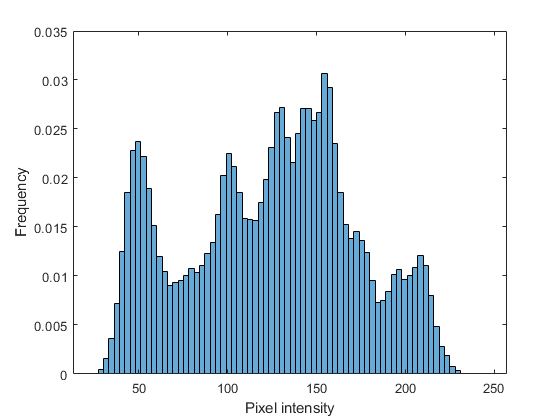

entropy = 5.8627

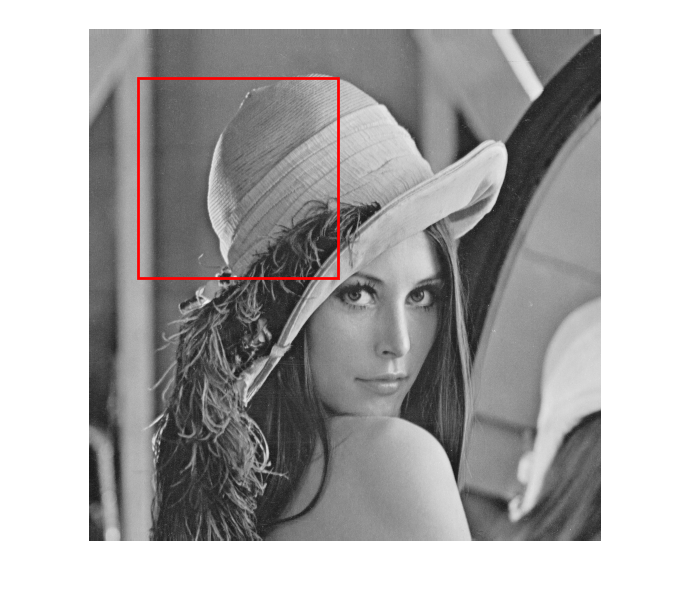

 Reference codelength: 320000


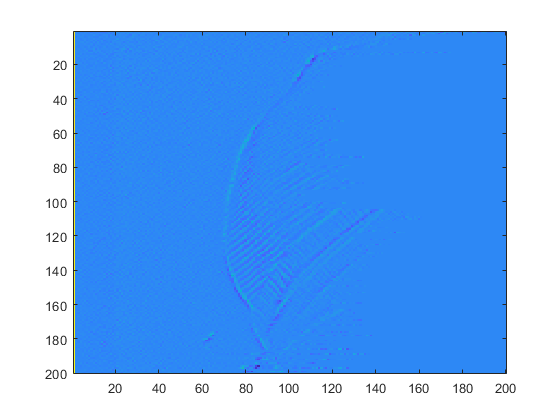

Golomb-Rice without blocking
Compression time: 3.6654s Decompression time: 0.29872s
Compressed size: 22.1kB (Codelength 181448)
Bits per pixel: 4.5354
Total compression error (should be 0): 0


image_compress(image_name, 'compressed.bin');

Golomb-Rice with blocking


bpp_CL =     3.7674    3.7662    3.7831    3.7708    3.7732    3.7767    3.7801    3.7847    3.7902    3.7949    3.8003    3.8046    3.8074    3.8122    3.8161    3.8192    3.8246    3.8284    3.8302    3.8354    3.8390    3.8423    3.8438    3.8460    3.8493    3.8508    3.8527    3.8546    3.8600    3.8611    3.8644    3.8642    3.8719    3.8712    3.8729    3.8746    3.8808    3.8838    3.8800    3.8851


Optimal block size: 100
Compression time: 4.0489s Decompression time: 0.50719s
Compressed size: 18.4kB (Codelength 150696)


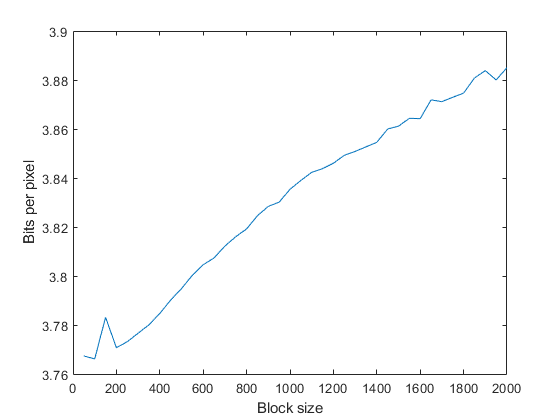

Total compression error (should be 0): 0



% Try with blocking
image_compress(image_name, 'compressed_with_blocking.bin', 'GRBlock', false);


% Try with Huffman
image_compress(image_name, 'compressed_huffman.bin', 'Huffman', false);

Huffman coding
Ideal codelength (with BPP=entropy=3.4816): 139265.8422
Compression time: 0.2968s Decompression time: 0.84746s
Compressed size: 17.1kB (Codelength 140545)
Bits per pixel: 3.508
Total compression error (should be 0): 0


% Image codecs
A = imread(image_name);
B = A(50:249, 50:249);

imwrite(B, 'compressed.png', 'png', 'Mode', 'lossless');
imwrite(B, 'compressed.jp2', 'jp2', 'Mode', 'lossless');
imwrite(B, 'compressed.jpeg', 'jpeg', 'Mode', 'lossless');

% Compare sizes
disp(['Compressed size using png: ' human_readable_file_size('compressed.png')])

Compressed size using png: 24.2kB


disp(['Compressed size using jp2: ' human_readable_file_size('compressed.jp2')])

Compressed size using jp2: 22.8kB


disp(['Compressed size using jpeg: ' human_readable_file_size('compressed.jpeg')])

Compressed size using jpeg: 25.8kB


disp(['Compressed size using plain GR: ' human_readable_file_size('compressed.bin')])

Compressed size using plain GR: 22.1kB


disp(['Compressed size using blockwise GR: ' human_readable_file_size('compressed_with_blocking.bin')])

Compressed size using blockwise GR: 18.4kB


disp(['Compressed size using Huffman: ' human_readable_file_size('compressed_huffman.bin')])

Compressed size using Huffman: 17.1kB
